Continuous

clear all;
close all;
clc;

lb = 0

lb = 0

rb = 10

rb = 10


% continuous
syms f1 f2 x
f1 = 1 + x.*(sin(x)).^2

$$f1 = x\,{\sin\left(x\right)}^{2}+1$$

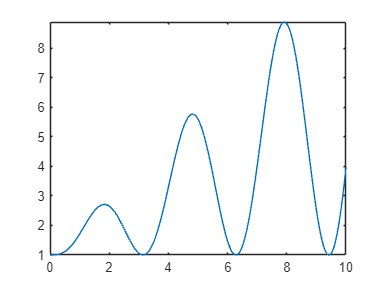

% f2 = 1 - x.*(sin(x)).^2
figure;
fplot(f1,[lb,rb]);

% hold on;
% fplot(f2,[lb,rb]);
% hold off

% Discrete

samples = 128

samples = 128

spacing_type = 'log' %'lin' or 'log'

spacing_type = 'log'


if strcmp(spacing_type,'log')
    x_dis = logspace(log10(1E-4),log10(rb),samples)
elseif strcmp(spacing_type,'lin')
    x_dis = linspace(lb,rb,samples)
else
    error('Spacing type not given')
end

x_dis =     0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0020    0.0022    0.0024    0.0026    0.0029    0.0031    0.0034    0.0038    0.0041    0.0045    0.0049    0.0054    0.0059    0.0065    0.0071    0.0078    0.0085


f1_dis = 1 + x_dis.*(sin(x_dis)).^2

f1_dis =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


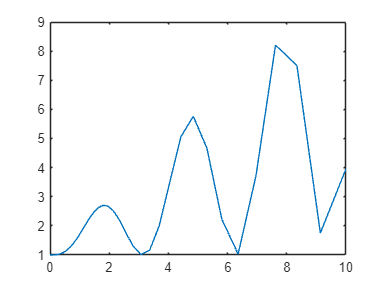

% f2_dis = 1 - x_dis.*(sin(x_dis)).^2
figure;
plot(x_dis,f1_dis)

% hold on
% plot(x_dis,f2_dis)
% hold off

%%% Statistics

%% Discrete

%mean
mu = mean(mean(f1_dis)) % + mean(f2_dis)

mu = 1.4286


%std
stan_dev = std([f1_dis]) % ,f2_dis

stan_dev = 1.1540


%skewness
skns = skewness([f1_dis]) %,f2_dis

skns = 3.8012


%kurtosis
kts = kurtosis([f1_dis]) % ,f2_dis

kts = 18.8487


%% Continuous

%mean
mu_cont = eval((int(f1,x,lb,rb))/(rb - lb)) %+int(f2,x,lb,rb)

mu_cont = 3.2792


%std
stan_dev_cont = eval((int((f1-mu_cont)^2,lb,rb)/(rb-lb))^0.5) %,f2_dis

stan_dev_cont = 2.2704


%skewness
skns_cont = eval(int((f1-mu_cont)^3,lb,rb)/((rb-lb)*stan_dev_cont^3))

skns_cont = 1.0211


%kurtosis
kts_cont = eval(int((f1-mu_cont)^4,lb,rb)/((rb-lb)*stan_dev_cont^4))

kts_cont = 2.9593

## Reconstruction

order = 15;
coeff = polyfit(x_dis,f1_dis,order);

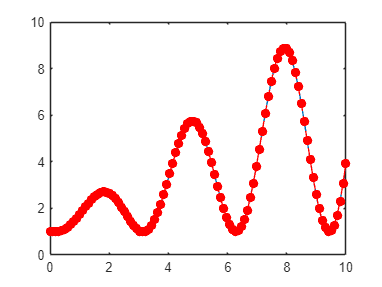

f_dis_polyfit = polyval(coeff,x_dis);

figure;
plot(x_dis,f1_dis)
hold on;
plot(x_dis,f_dis_polyfit,'--or','LineWidth',1,'MarkerFaceColor','r')
hold off

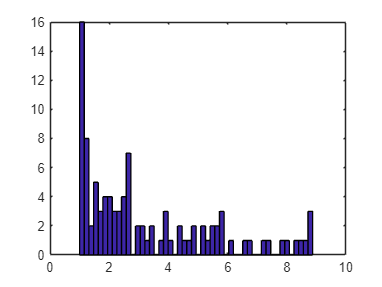


hist(f1_dis,50)